# Proyecto SCV

Definición de parámetros.

p = struct(); 

p.m    = 230;      % masa [kg]                              
p.g    = 9.81;     % gravedad [m/s^2]
p.rho  = 1.225;    % densidad del aire [kg/m^3]
p.Cd   = 1.0;      % coef. aerodinámico                       
p.Af   = 1.1;      % área frontal [m^2]                        
p.fr  = 0.022;    % coef. de resistencia a la rodadura       
p.Fx_drive_max = 2500;   % fuerza motriz máxima [N]           
p.Fx_brake_max = 5000;   % fuerza de frenado máxima [N]       
p.theta        = 0;      % inclinación de la calzada [rad]

% adherencia por eje
p.mu_t = 1.5; 
p.mu_d = 0.95*p.mu_t; 

% dinámica lateral del vehículo
p.ld = 0.765; % CG-eje delantero [m] 
p.lt = 0.765; % CG-eje trasero [m]
p.Iz = 130; % inercia en guiñada [kg·m^2]
p.Cad = 35000; % rigidez de deriva delantera [N/rad]
p.Cat = 50000; % rigidez de deriva trasera [N/rad]

% Ley ACC 

p.d0 = 6; % distancia mínima de parada [m]
p.h = 1.5; % umbral de tiempo ("headway") [s]
p.Kv = 1.5; % ganancia modo velocidad
p.Kg = 0.4; % Ganancia modo distancia 
p.Kd = 1.0; % Ganancia derivativa sobre velocidad relativa 
p.jerk_max = 2.5; % tasa de variación de la aceleración (sobreaceleración; min sacudidas max confort) [m/s^3]

% propios de la simulación (esto es para no tener que ejecutar una cosa y
% otra primero para que funcione) 
p.v_set = 25; % velocidad de crucero deseada [m/s] (90 km/h) 
p.dt = 0.002; % paso de la simulación 
esc.lead_X0 = 30; % posición inicial del lider [m]
esc.Tmax = 22; % tiempo máx simulación

#### Modelo del vehículo

% Integración de la dinámica longitudinal y lateral

% u: variable de control = [Fx; delta] 
% z: vector de estados del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada




#### Controlador de velocidad

#### Geometría del circuito de pruebas

function hist = simularE4(z0, p, esc, dt)
    % El ego se modela como bicicleta (P2) con delta = 0 + coche líder guionizado. 
    N = round(esc.Tmax/dt);  z = z0;
    Xl = esc.lead_X0; % posición del líder
    mem.Fx_prev = 0; % memoria del controlador
    hist.t=zeros(1,N); hist.vx=zeros(1,N); hist.vl=zeros(1,N);
    hist.Xe=zeros(1,N); hist.Xl=zeros(1,N); hist.gap=zeros(1,N);
    hist.d_des=zeros(1,N); hist.Fx=zeros(1,N);
    for k = 1:N
        t = (k-1)*dt;
        Vl = liderVel(t);  % velocidad del líder 
        Xl = Xl + Vl*dt;   % integra su posición

        % OJO! esto es una simplificación: el estado estimado es la realidad
        est.X = z(1);  est.vx = z(4);

        ref.v_set = p.v_set;  ref.lead_X = Xl;  ref.lead_vx = Vl;

        [Fx, mem] = controlLongitudinal(est, ref, p, mem);

        z = pasoDinamico(z, [Fx;0], p, dt);   % delta = 0: recta

        hist.t(k)=t; hist.vx(k)=z(4); hist.vl(k)=Vl;
        hist.Xe(k)=z(1); hist.Xl(k)=Xl; hist.gap(k)=Xl - z(1);
        hist.d_des(k)=p.d0 + p.h*z(4); hist.Fx(k)=Fx;
    end
end

function Vl = liderVel(t)
% Perfil de velocidad del líder: acelera, crucero, frena.
    v_cru = 18; % 65 km/s
    if t < 8
        Vl = min(v_cru, 2.5*t);            % acelera
    elseif t < 14
        Vl = v_cru;                        % crucero
    else
        Vl = max(8, v_cru - 3*(t-14));     % frena a 8 m/s (30 km/s)
    end
end

#### Simulación

dt = p.dt;
z0 = [0; 0; 0; 0; 0; 0]; % estado inicial
% u: variable de control [Fx; delta]
% z: vector de estado del vehículo [X; Y; psi; vx; vy; r]
% X, Y = posicion del CG global
% psi = rumbo, ángulo de guiñada
% vx, vy = velocidades en eje del chasis
% r = velocidad de guiñada

hist = simularE4(z0, p, esc, dt); 

#### Resultados

% Cálculo de las métricas de seguridad
gap_min = min(hist.gap);

fprintf('ACC — separación mínima: %.1f m  (líder frena en t=14 s)\n', gap_min);

ACC — separación mínima: 19.4 m  (líder frena en t=14 s)


if gap_min <= 0
    fprintf('  ¡COLISIÓN! (la ley ACC no mantiene la distancia)\n');
else
    fprintf('  sin colisión: separación siempre > 0\n');
end

  sin colisión: separación siempre > 0


fprintf('  velocidad final ego: %.1f km/h | líder: %.1f km/h\n', ...
        hist.vx(end)*3.6, hist.vl(end)*3.6);

  velocidad final ego: 30.3 km/h | líder: 28.8 km/h


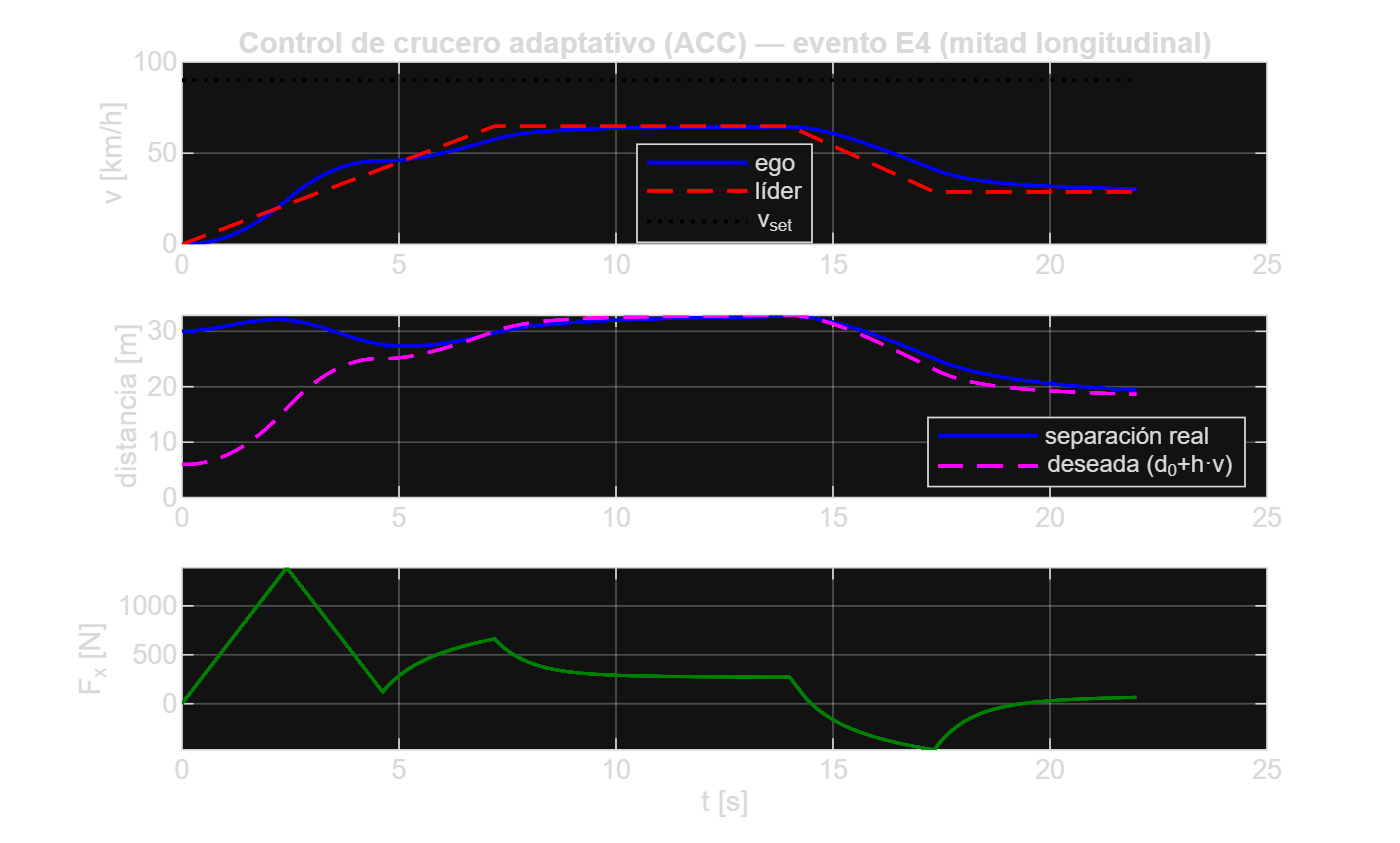

% gráficas
figure('Name','L3 · ACC','Color','w');
subplot(3,1,1);
  plot(hist.t, hist.vx*3.6,'b', hist.t, hist.vl*3.6,'r--', hist.t, p.v_set*3.6*ones(size(hist.t)),'k:','LineWidth',1.2);
  ylabel('v [km/h]'); grid on; legend('ego','líder','v_{set}','Location','best');
  title('Control de crucero adaptativo (ACC) — evento E4 (mitad longitudinal)');
subplot(3,1,2);
  plot(hist.t, hist.gap,'b', hist.t, hist.d_des,'m--','LineWidth',1.2);
  ylabel('distancia [m]'); grid on; legend('separación real','deseada (d_0+h·v)','Location','best');
subplot(3,1,3);
  plot(hist.t, hist.Fx,'Color',[0 .5 0],'LineWidth',1.2);
  ylabel('F_x [N]'); xlabel('t [s]'); grid on;